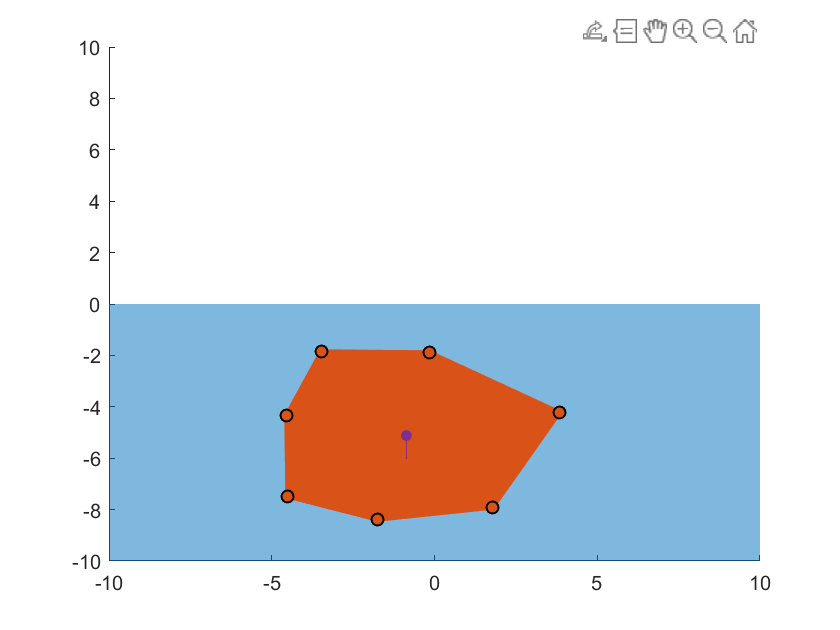

clear all
close all

Rho_Liquid = 1000.0;
Rho_Material = 100.0;
Depth = 5.0;
g = 9.81;


axis([-10 10 -10 10]);
w = patch([-10 10 10 -10], [-10 -10 0 0], 'k','FaceColor', '#0072BD', 'FaceAlpha', 0.5, 'LineStyle', 'none');
pol = drawpolygon("FaceAlpha", 1.0, "Color",[0.8500 0.3250 0.0980]);
pol = polyshape(pol.Position);
[xc, yc] = centroid(pol);
hold on
scatter(xc, yc, 30, "filled", "SeriesIndex", 4)
Fg = [0; -Rho_Material*g*Depth*area(pol)];
quiver(xc,yc, Fg(1)/norm(Fg), Fg(2)/norm(Fg), 'SeriesIndex', 4)

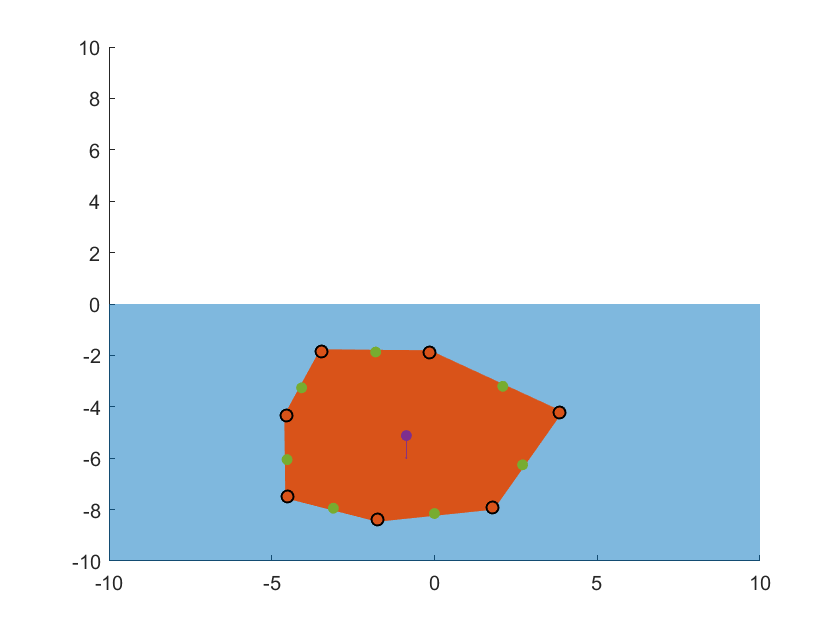

numedge = size(pol.Vertices,1);
for e = 1:numedge
    if (e ~= numedge)
        xe = [pol.Vertices(e,1) pol.Vertices(e+1,1)];
        ye = [pol.Vertices(e,2) pol.Vertices(e+1,2)];
    else
        xe = [pol.Vertices(end,1) pol.Vertices(1,1)];
        ye = [pol.Vertices(end,2) pol.Vertices(1,2)];
    end
    y = @(h) (1-h)*ye(1) + h*ye(2);
    x = @(h) (1-h)*xe(1) + h*xe(2);
    P  = @(h) -( y(h) < 0 ).*Rho_Liquid*g.*y(h);
    Ph = @(h) -( y(h) < 0 ).*Rho_Liquid*g.*y(h).*h;
    Pint = integral(P, 0, 1);
    if ( Pint ~= 0.0 )
        hp = integral(Ph, 0, 1)/Pint;
        Cp = [x(hp), y(hp) ];
        scatter(Cp(1), Cp(2), 30, "filled", "SeriesIndex", 5);
    end
end